# Test Script for the STM32 DSP Pipeline

Author: Michael Noyce

Description: Compares the processing done in MATLAB vs the signal processing done on the STM32. 

## Calibration Function 

Textfile = load("calibratedOutput.txt")

Textfile = 	1.0e+23 *

   -0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000


writematrix(Textfile, "calibratedOutput.csv");
calibratedOutput = readtable("calibratedOutput.csv");

T = 0.01;
N = height(calibratedOutput(:,1))

N = 2048

t = (0:N-1)*T;        % Time vector

figure();
plot(t, accZCal(20000:20000+N-1, 1), t, calibratedOutput{:, 1});
title('IMU Platform Calibrated acceleration values in m/s^2')
legend("X", "Y", "Z")

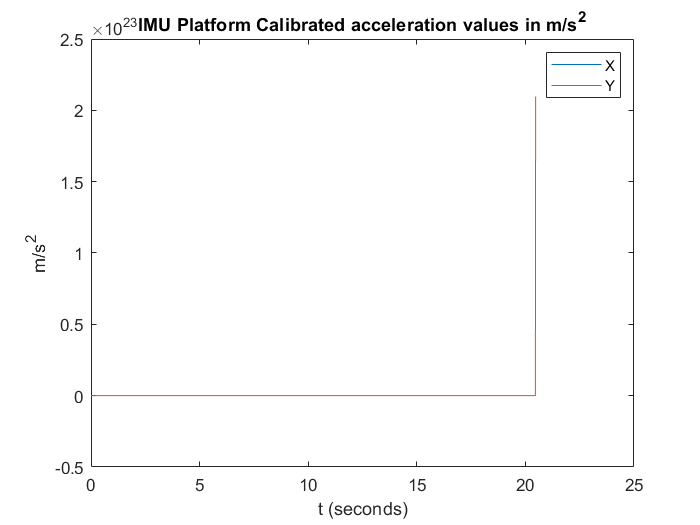

xlabel('t (seconds)')
ylabel('m/s^2')

## Detrend Function 

Textfile = load("detrendedOutput.txt")

Textfile =     0.0850
    0.0684
    0.0873
    0.0422
    0.0920
    0.0919
    0.0468
    0.1203
    0.0847
    0.1012


writematrix(Textfile, "detrendedOutput.csv");
detrendedOutput = readtable("detrendedOutput.csv");

T = 0.01;
N = height(detrendedOutput(:,1))

N = 1000

t = (0:N-1)*T;        % Time vector

figure();
plot(t, accZ(1, 20000:20000+N-1), t, detrendedOutput{:, 1});
title('IMU Platform detrended acceleration values in m/s^2')
legend("X", "Y", "Z")

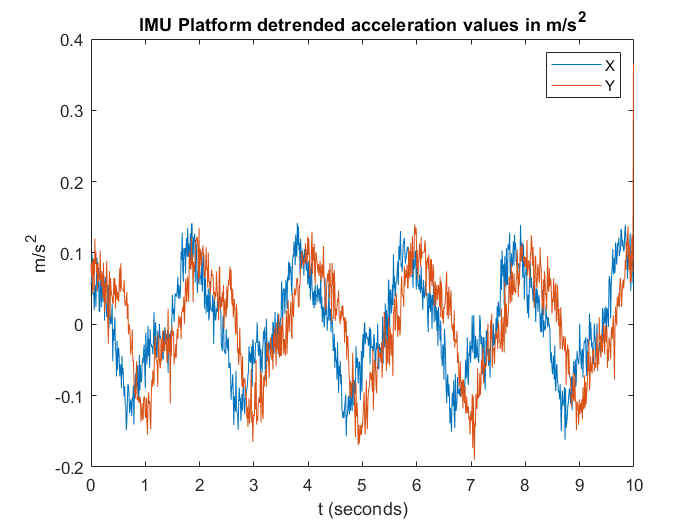

xlabel('t (seconds)')
 ylabel('m/s^2')

## LPF and Decimate function

% Textfile = load("decimatedOutput.txt")
% writematrix(Textfile, "decimatedOutput.csv");
% detrendedOutput = readtable("decimatedOutput.csv");
% 
% T = 0.01;
% N = height(detrendedOutput(:,1))
% t = (0:N-1)*T;        % Time vector
% 
% figure();
% plot(t, accZ(1, 20000:20000+N-1), t, detrendedOutput{:, 1});
% title('IMU Platform detrended acceleration values in m/s^2')
% legend("MATLAB", "STM32")
% xlabel('t (seconds)')
%  ylabel('m/s^2')
%  


## Four Step FFT Function 

Textfile = load("captureFFT.txt")

Textfile = 	1.0e+03 *

    0.4500
    0.0026
    0.0031
    0.0814
    0.1511
    1.0164
    0.1888
    0.1777
    0.0925
    0.0737


writematrix(Textfile, "captureFFT.csv");
FFTOutput = readtable("captureFFT.csv");

T = 0.01;
N = height(FFTOutput{:,1})

N = 5120

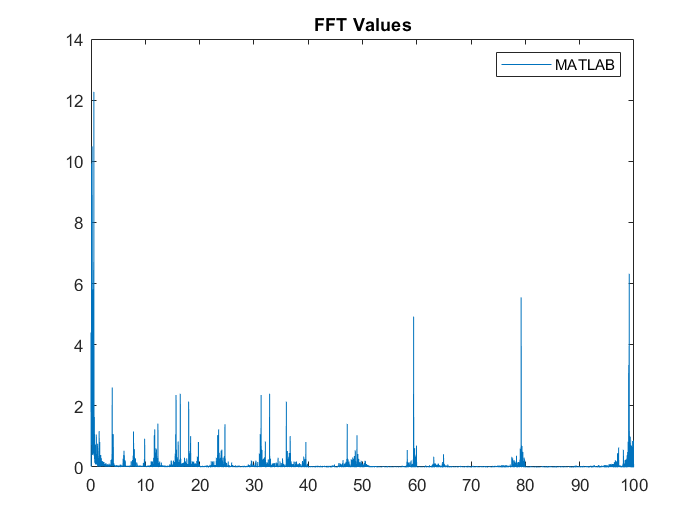

t = (0:N-1)*T;        % Time vector

Z = FFTOutput{:,1}*100/2;

L = length(Z);
P2 = abs(Z/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = 100*(0:(L-1))/L;

figure();
plot(f, P2);
title('FFT Values');
legend("MATLAB", "STM32")